# TEMPERATURE AND SPEED CONTROL LAB (TSC-LAB)

#### Práctica 5: Activation of Transistor 1 and 2, also Reading of temperature sensor 1 and 2

[https://tsc-lab.blogspot.com/2021/05/practica-5-activation-of-transistor-1.html](https://tsc-lab.blogspot.com/2021/05/practica-5-activation-of-transistor-1.html)

- Blog: [https://tsc-lab.blogspot.com/](https://tsc-lab.blogspot.com/)

- GitHub: [https://github.com/vasanza/TSC-Lab](https://github.com/vasanza/TSC-Lab)

- Matlab functions: [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `IEEEDataPort: `[http://ieee-dataport.org/4138](http://ieee-dataport.org/4138)

- `TSC-LAB configurations`

- `int period = 15; //medium period in minutes`

- `int freq_sampling = 100; // sampling time`

- `int ciclos = 20; // sampling time`

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder

# Raw dataset preprocessing

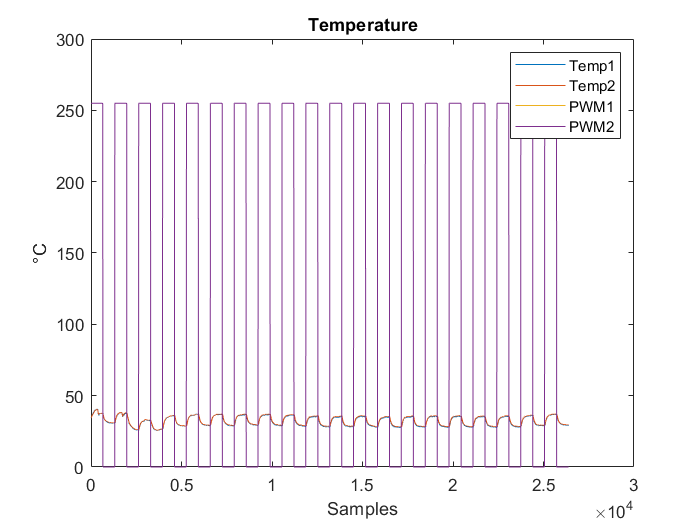

filenames = FindCSV(datapath);%List All CSV files
data=readtable(fullfile(datapath,filenames(1).name));%Select i CSV file
data=table2array(data);
DataNorm = fNormalization(data(:,1:2));%Normalization
DataFeatures = [max(DataNorm) min(DataNorm) mean(DataNorm)...

    median(DataNorm) rms(DataNorm) std(DataNorm) ];%Feature extraction

# Plot Raw TSC-LAB dataset

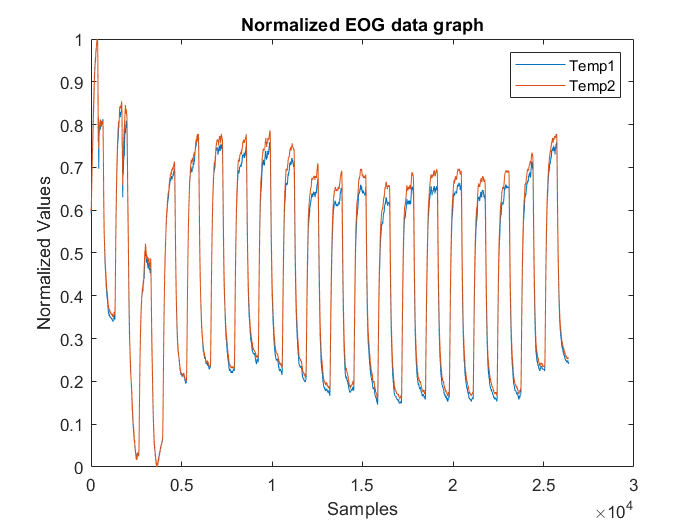

figure
plot(data);xlabel('Samples');ylabel('°C');
title('Temperature');

legend('Temp1','Temp2','PWM1','PWM2');

# Plot Normalization EOG dataset

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized EOG data graph');
legend('Temp1','Temp2');

# Select a case

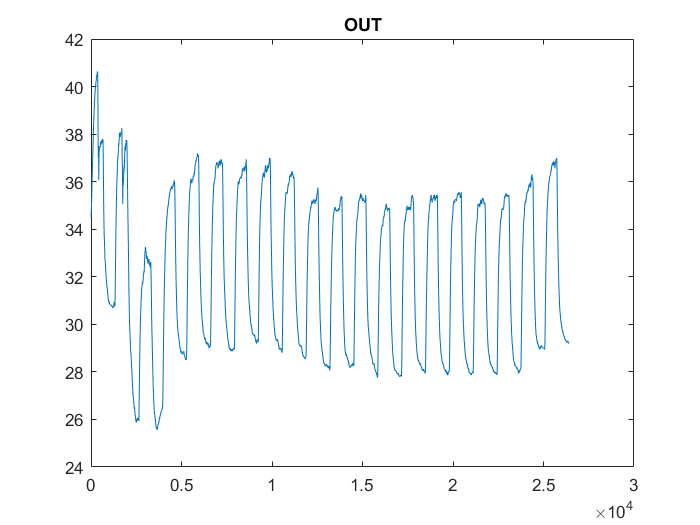

num = input('Enter a case: ');
switch num
    case 1 %Temp1
        IN=data(:,end-1);%temp1
        OUT=data(:,1);%PWM1
case 2 %Temp2
        IN=data(:,end);%temp1
        OUT=data(:,2);%PWM1
    case 3 %Temp1 and Temp2
        IN=[(data(:,end) + data(:,end-1))/2];%temp1

                                                                    
Created preference file C:\Users\vasan\Documents\MATLAB\idprefs.mat.
Type HELP MIDPREFS if you want to move this file.                   


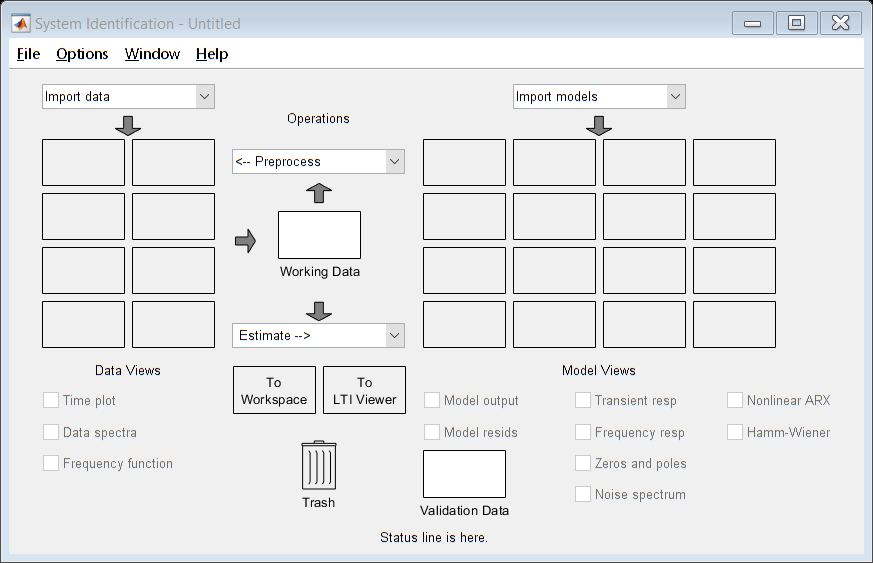

        OUT=data(:,1);%PWM1
end
figure

plot(OUT)
title('OUT');

# System Identification

ident

# Open the Classification Learner

%regressionLearner
%classificationLearner